## Parcial 1 - Análisis Numérico                      30/08/2023

**Santiago Hoyos Ortiz**

Una de las aplicaciones de la interpolación polinomial consiste en emplear polinomios obtenidos mediante técnicas como polinomios de Lagrange o splines cúbicos. La siguiente es la “función de jorobas integradas” que usa Matlab para demostrar algunas de sus capacidades numéricas:

clear
syms x
x_i = [0.05, 0.08, 0.1, 0.15, 0.2, 0.25, 0.3, 0.45, 0.5, 0.6, 0.65, 0.7, 0.8, 0.85, 0.9, 0.95, 0.98, 1];
%[0.05, 0.1, 0.15, 0.2, 0.25, 0.3, 0.35, 0.4, 0.45, 0.5, 0.55, 0.6, 0.7, 0.8, 0.85, 0.9, 0.95];

f = @(x) 1/((x - 0.3)^2 + 0.01) + 1/((x - 0.9)^2 + 0.04);
y_i = arrayfun(f, x_i);
n = length(x_i);

% Calculando el polinomio interpolador de Lagrange
P = 0;

for i = 1:n
    L = 1;
    for j = 1:n
        if j ~= i
            L = L * (x - x_i(j)) / (x_i(i) - x_i(j));
        end
    end
    P = P + y_i(i) * L;
end

% Simplificando el polinomio
simplified_P = simplify(P);

% Imprimiendo el polinomio interpolador simplificado
disp("Polinomio interpolador de Lagrange simplificado:");

Polinomio interpolador de Lagrange simplificado:


disp(simplified_P);

**1. (3 puntos) Ajuste la función mediante polinomios de interpolación de Lagrange comprobando, gráficamente, que la interpolación aproxima de forma adecuada la curva original.**

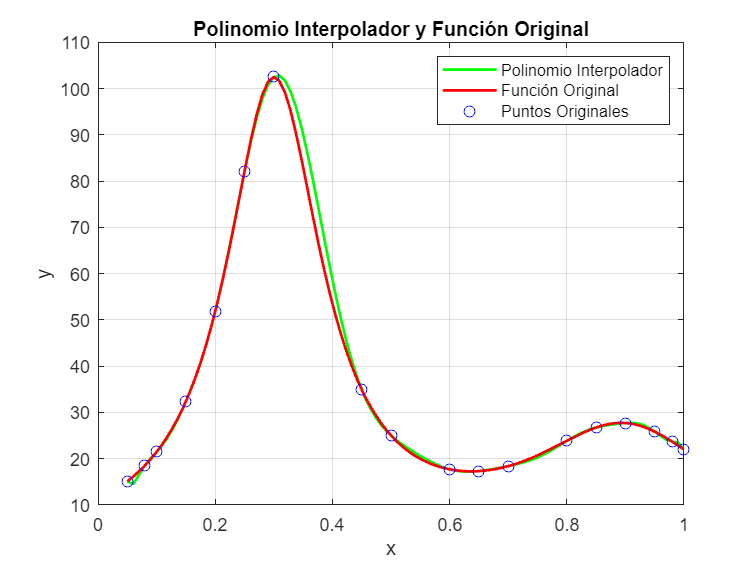

% Crear un vector de valores x para la función original
x_original = linspace(min(x_i), max(x_i), 100);
y_original = 1./((x_original - 0.3).^2 + 0.01) + 1./((x_original - 0.9).^2 + 0.04);

% Graficar el polinomio interpolador
x_eval = linspace(min(x_i), max(x_i), 100);
P_eval = subs(simplified_P, x, x_eval);

figure;
% Graficar el polinomio interpolador
plot(x_eval, P_eval, 'g', 'LineWidth', 1.5);
hold on;

% Graficar la función original
plot(x_original, y_original, 'r', 'LineWidth', 1.5);

% Graficar los puntos originales
scatter(x_i, y_i, 'bo');

title('Polinomio Interpolador y Función Original');
xlabel('x');
ylabel('y');
legend('Polinomio Interpolador', 'Función Original', 'Puntos Originales');
grid on;

**2. (1 puntos) A partir de la interpolación obtenida, calcule el valor de 𝑥 que se obtiene para 𝑓(𝑥) = 45. **

% Deseo encontrar su correspondiente x
target_f_x = 45; 

% Evaluar el polinomio interpolador en intervalos pequeños de x
x_eval = linspace(min(x_i), max(x_i), 1000);

% Inicializar variables
approx_x = NaN;       % Valor de x aproximado correspondiente a target_f_x
approx_error = Inf;   % Error absoluto mínimo encontrado

% Iterar a través del polinomio interpolador y encontrar el x correspondiente a target_f_x
for i = 1:length(x_eval)
    f_x_eval = subs(simplified_P, x, x_eval(i));
    
    % Encontrar la diferencia mínima entre target_f_x y los valores evaluados
    diff = abs(f_x_eval - target_f_x);
    
    % Actualizar si se encontró una diferencia más pequeña
    if diff < approx_error
        approx_error = diff;
        approx_x = x_eval(i);
    end
end

disp(['Valor de x aproximado para f(x) = ', num2str(target_f_x), ': ', num2str(approx_x)]);

Valor de x aproximado para f(x) = 45: 0.42467


**Punto 3. (1 puntos) Usando una estrategia diferente a la del punto 2, calcule el valor de 𝑥 que se obtiene para 𝑓(𝑥) = 22.**

%BISECCIÓN

% f(x)
f = @(x) 1/((x - 0.3)^2 + 0.01) + 1/((x - 0.9)^2 + 0.04) - 22;

a = 0;  % Límite inferior
b = 1;  % Límite superior

% Tolerancia para la convergencia
tolerance = 1e-6;

% Utilizar la función de bisección
x_root = bisection_method(f, a, b, tolerance);

% Mostrar el valor de x que corresponde a f(x) = 22
disp(['Valor de x para f(x) = 22: ', num2str(x_root)]);

Valor de x para f(x) = 22: 0.10318


function root = bisection_method(func, a, b, tolerance)
    if func(a) * func(b) > 0
        error('La función no cumple con el teorema de Bolzano en el intervalo proporcionado.');
    end
    
    while (b - a) / 2 > tolerance
        c = (a + b) / 2;
        
        if func(c) == 0
            root = c;
            return;
        elseif func(c) * func(a) < 0
            b = c;
        else
            a = c;
        end
    end
    
    root = (a + b) / 2;
end